# Monopulse Tracking Lab

In this lab, we use the monopulse array processing technique to measure the off-boresight angle of a transmitter and use these measurements in a Kalman filter to track the off-boresight angle of the transmitter.

Before running this lab, ensure that you have already collected the calibration weights using the "Calibrate Antenna" livescript.

## Setup

First, put the HB100 transmitter as close to boresight as possible. For this lab to work, the transmitter has to start at boresight.

Run the following to clear the workspace.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

We also load the calibration weights which are applied so that the beam pattern matches our expectations.

load('CalibrationWeights.mat','calibrationweights');

### Identify HB100 Frequency

Before collecting any data, we need to identify the operating frequency of the HB100. Run the following script to do so.

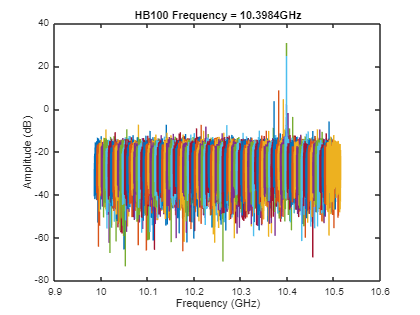

fc_hb100 = findTxFrequency();

### Collect Monopulse Pattern

Once the frequency of the HB100 has been identified, we collect the monopulse pattern for the array. With this pattern, we can identify the angle of the transmitter with only a single measurement by looking at the phase different and magnitude ratio between the sum and difference patterns.

We collect the pattern for 12.5 degrees on either side of boresight. The target azimuth becomes ambiguous outside of this region.

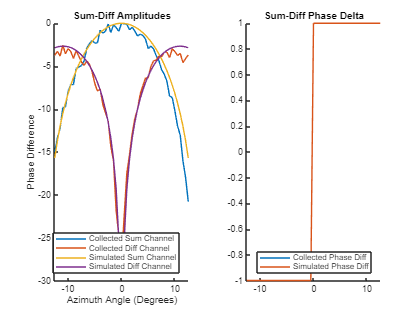

[monopulsePattern,~] = createMonopulsePattern(fc_hb100,calibrationweights,0,12.5);

### Create Antenna Interactor

The antenna interactor object helps us to interact with the phaser board to steer the beam and collect data. Create this object so that we can control the antenna.

ai = AntennaInteractor(fc_hb100,calibrationweights);

### Monopulse Tracking

In this section, we run the monopulse tracking system. First we setup the tracking parameters.

### Tracking Parameters

Next we setup the parameters that define our motion and measurement models for our Kalman filter.

Measure the initial target angle by scanning the radar beam. This approach is accurate but slow to use for tracking. We do this to measure the initial position of the transmitter.

angles = -90:90;
startpat = helperGetAmplitude(ai.capturePattern(angles));
[~,angIdx] = max(abs(startpat));

Setup the initial state. The state consists of the target angle and target angular velocity.

x0 = [angles(angIdx);0];

Setup the initial covariance, we assume that the transmitter is starting within ~10 degrees of boresight and is not moving.

P0 = diag([10;2]);

Define the motion model. We make it a function handle so that dt can vary throughout the simulation.

F = @(dt)[1 dt;0 1];

Define the motion model covariance.

Q = diag([2^2;5^2]);

Define the measurement model. We only measure the target angle, the target angular velocity is not measured directly.

H = [1 0];

Define the measurement error, which is made up of both the steering error and monopulse error.

R = 4^2;

Define the number of measurements to run.

K = 500;

Initialize the state and measurement variables.

xhat = nan(2,K+1);
Phat = zeros(2,2,K+1);
theta_hat = zeros(1,K);
xhat(:,1) = x0;
Phat(:,:,1) = P0;

### Collect Data

With the tracking parameters setup, we collect data and track the target angle.

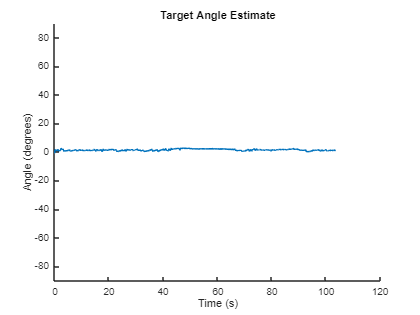

% Setup axes to plot angles
ax = axes(figure);
hold(ax,"on");
angline = plot(ax,0,0);
title(ax,"Target Angle Estimate");
xlabel(ax,"Time (s)");
ylabel(ax,"Angle (degrees)");
ylim([-90 90]);

% Track the current time for motion updates
tic;
t = nan(1,K+1);
t(1) = 0;

% Tracking
for k = 1:K
    % Motion update
    tcurrent = toc;
    dt = tcurrent - t(k);
    t(k+1) = tcurrent;
    xm = F(dt)*xhat(:,k);
    Pm = F(dt)*Phat(:,:,k)*F(dt).'+Q;
    
    % Make measurement by steering to predicted target angle and measuring
    % angle off of center using monopulse processing
    steerangle = xm(1);
    [sdr,pd] = ai.captureMonopulsePattern(steerangle);
    oba = estimateMonopulseAngle(monopulsePattern,sdr,pd);
    theta_hat(k) = steerangle-oba;

    % information update
    S = H*Pm*H.'+R;
    G = (Pm*H.')/S;
    xhat(:,k+1) = xm+G*(theta_hat(k)-H*xm);
    Phat(:,:,k+1) = Pm-G*H*Pm;

    % Plot the estimated angles
    set(angline,'XData',t,'YData',xhat(1,:));
    
    drawnow;
end

## Helper Function

function angle = estimateMonopulseAngle(pattern,sumdiffratio,phasedelta)
    % Return angle of 0 if phase delta is 0
    if phasedelta == 0
        angle = 0;
        return
    end
    
    % Extract monopulse pattern values
    oba = pattern.OBA;
    ampdeltapattern = pattern.SumDiffAmpDelta;
    phasedeltapattern = pattern.SumDiffPhaseDelta;

    % Get the values with the correct phase delta
    validphase = phasedeltapattern == phasedelta;
    validoba = oba(validphase);
    validampdelta = ampdeltapattern(validphase);

    % If the sumdiffratio is outside of bounds, set angle to boundary
    % value. Otherwise interpolate to get angle.
    [maxsdr,maxidx] = max(validampdelta);
    [minsdr,minidx] = min(validampdelta);
    if maxsdr < sumdiffratio
        angle = validoba(maxidx);
    elseif minsdr > sumdiffratio
        angle = validoba(minidx);
    else
        angle = interp1(validampdelta,validoba,sumdiffratio);
    end    
end